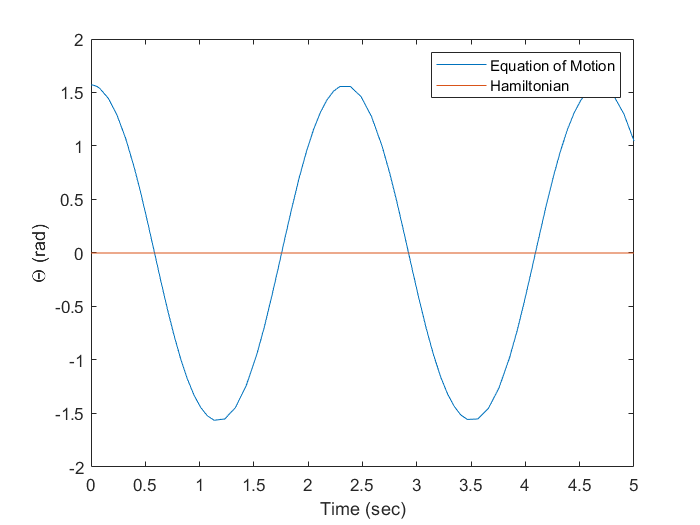

g=9.81;
R=1;
somega=1;
m=1;
theta_initial=[pi/2 0]; %Theta initial condition
time_line=[0 5];
odefun=@(t,theta) [theta(2);...% first ODE
    -m*somega^2*sin(theta(1)).*cos(theta(1))-m*g*sin(theta(1))/R]; % second ODE
[t,theta]=ode45(odefun , time_line, theta_initial);
plot(t, theta(:,1))
xlabel('Time (sec)')
ylabel('\Theta (rad)')
hold on
syms H(t)                 %Lets assume Hamiltonian(H) as a function of time
eq=@(t,H) [H(2)==0; 0];    %we know that first and second order derivative of H is zero          
[t, H]=ode45(eq, [0 5], [0 inf]); %Even if we have H vary from 0 to infinty.
plot(t,H(:,1))                  %when plotted against time we see that H is a constant.
legend('Equation of Motion','Hamiltonian')